clear
load CHARACTERISTICS_WORKSPACE_1_1.mat
idx0_vel = find(vel == 0);
idx0_vel_beg = idx0_vel(1)

idx0_vel_beg = 336

idx0_vel_end = idx0_vel(end)

idx0_vel_end = 19647


trimmed = false;

if trimmed == false
    times = times(idx0_vel_beg:idx0_vel_end);
    timeConst = timeConst(idx0_vel_beg:idx0_vel_end);
    vel = vel(idx0_vel_beg:idx0_vel_end);
    throttle = throttle(idx0_vel_beg:idx0_vel_end);
    brake = brake(idx0_vel_beg:idx0_vel_end);
    trimmed = true;
end

throttleIdx = find(throttle == 1);
startThrottle = throttleIdx(1)

startThrottle = 1

endThrottle = throttleIdx(end)

endThrottle = 15093


brakeIdx = find(brake == 1) ;
brakeIdx_stop = find(abs(vel) > 10e-4);
startBrake = brakeIdx(1)

startBrake = 15094

endBrake = brakeIdx_stop(end)

endBrake = 16162


throttle_vel = vel(startThrottle:endThrottle);
time_throttle = times(startThrottle:endThrottle);
time_throttle = time_throttle - time_throttle(1);

brake_vel = vel(startBrake:endBrake);
time_brake = times(startBrake:endBrake);
time_brake = time_brake - time_brake(1);

for i=1:length(brake_vel)-1
    distance = trapz(time_brake(i:end),brake_vel(i:end));
    brakeDistance(i) = distance;
end

str = "{";
brakeDistance = flip(brakeDistance)

brakeDistance =     0.0000    0.0004    0.0015    0.0021    0.0029    0.0040    0.0146    0.0170    0.0225    0.0267    0.0290    0.0316    0.0373    0.0434    0.0484    0.0574    0.0632    0.0734    0.0995    0.1341    0.1560    0.1585    0.1693    0.1861    0.1891    0.1952    0.2016    0.2509    0.2576    0.2785    0.2856    0.2892    0.3076    0.3263    0.3339    0.3957    0.4035    0.4274    0.4436    0.4518    0.4602    0.4813    0.5414    0.5458    0.5722    0.5812    0.6039    0.6085    0.6318    0.6365


brake_vel_int = flip(brake_vel(1:length(brakeDistance)))

brake_vel_int =     0.0118    0.1705    0.2145    0.3433    0.4751    0.6008    0.7287    0.8579    0.9838    1.0978    1.2250    1.3572    1.4748    1.6093    1.7287    1.8596    1.9843    2.1132    2.2394    2.3677    2.4943    2.6225    2.7490    2.8773    3.0035    3.1321    3.2572    3.3139    3.4303    3.5118    3.6107    3.6341    3.7184    3.7649    3.8334    3.8908    3.9543    4.0145    4.0766    4.1377    4.1994    4.2607    4.3223    4.3838    4.4454    4.5069    4.5685    4.6301    4.6917    4.7533



for i=1:length(brakeDistance)
    str = str + string(round(brake_vel_int(i),3)) + ":" + string(round(brakeDistance(i),3));
    
    if i ~= length(brakeDistance)
        str = str + ",";
        if mod(i,10) == 0 
        str = str + "\n";
        end
    end
    
    
end
str = str + "}"

str = "{0.012:0,0.17:0,0.214:0.002,0.343:0.002,0.475:0.003,0.601:0.004,0.729:0.015,0.858:0.017,0.984:0.023,1.098:0.027,\n1.225:0.029,1.357:0.032,1.475:0.037,1.609:0.043,1.729:0.048,1.86:0.057,1.984:0.063,2.113:0.073,2.239:0.1,2.368:0.134,\n2.494:0.156,2.622:0.159,2.749:0.169,2.877:0.186,3.003:0.189,3.132:0.195,3.257:0.202,3.314:0.251,3.43:0.258,3.512:0.278,\n3.611:0.286,3.634:0.289,3.718:0.308,3.765:0.326,3.833:0.334,3.891:0.396,3.954:0.404,4.015:0.427,4.077:0.444,4.138:0.452,\n4.199:0.46,4.261:0.481,4.322:0.541,4.384:0.546,4.445:0.572,4.507:0.581,4.568:0.604,4.63:0.608,4.692:0.632,4.753:0.637,\n4.815:0.651,4.877:0.656,4.938:0.666,5:0.685,5.062:0.695,5.124:0.695,5.185:0.716,5.247:0.82,5.309:0.873,5.371:0.884,\n5.433:0.895,5.494:0.922,5.556:0.933,5.618:0.944,5.68:0.95,5.742:0.996,5.804:1.007,5.866:1.03,5.928:1.036,5.99:1.102,\n6.052:1.108,6.114:1.12,6.176:1.132,6.238:1.17,6.3:1.182,6.362:1.321,6.425:1.328,6.487:1.367,6.549:1.373,6.611:1.386,\n6.673:1.419,6.736:1.493,6.798:1.5,6.86:1.507


fid = fopen('brake_lut.txt','wt');
fprintf(fid, str);
fclose(fid);

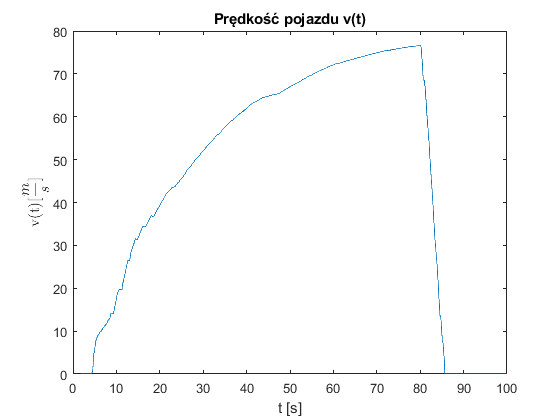

figure()
plot(times,vel)
title("Prędkość pojazdu v(t)")
xlabel("t [s]")
ylabel('v(t)[$\displaystyle\frac{m}{s}$]','interpreter','latex')

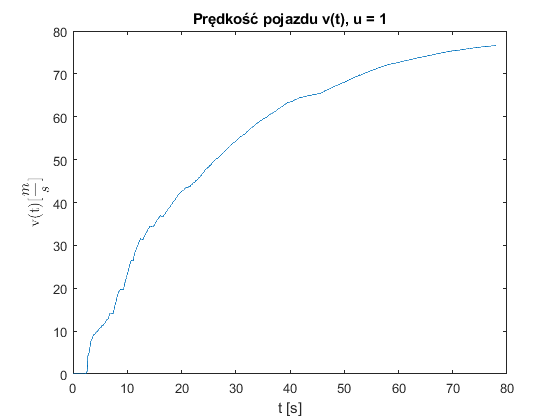


figure()
plot(time_throttle,throttle_vel)
title("Prędkość pojazdu v(t), u = 1")
xlabel("t [s]")
ylabel('v(t)[$\displaystyle\frac{m}{s}$]','interpreter','latex')

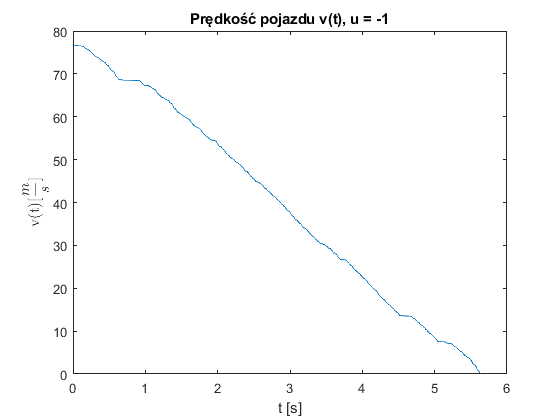


figure()
plot(time_brake,brake_vel)
title("Prędkość pojazdu v(t), u = -1")
xlabel("t [s]")
ylabel('v(t)[$\displaystyle\frac{m}{s}$]','interpreter','latex')

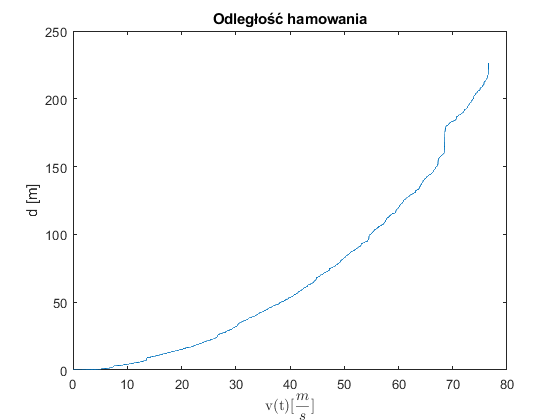


figure()
plot(brake_vel_int,brakeDistance)
title("Odległość hamowania")
xlabel('v(t)[$\displaystyle\frac{m}{s}$]','interpreter','latex')
ylabel("d [m]")